# The Braking energy required in the standard UDDS drive cycle.

## Braking energy generated by the given code and plotting them:


$$\left.\textrm{Braking}\;\textrm{Energy}=\frac{1}{2}m{{\left(v\right.}^2 }_f -{v^2 }_i \right)$$


%input values
mass = 1600;                        %Mass of vehicle
g = 9.8;                            %Acceleration due to gravity 
time_period = 126;                 %Time period
R = 0.355;                          %Raidus of wheel
Cr = 0.012;
N = 350;
B = 0.05;
L = 0.30;
Rx = 0.1;
num = xlsread('udds.xlsx');         %Reasing the drive cycle
time = num(1:time_period,1);        %time values(seconds)
velocity = num(1:time_period,2);    %velocity values(m/s)
decrease_in_velocity = zeros(1,time_period);
change_in_time = zeros(1,time_period);
deceleration = zeros(1,time_period);
braking_energy = zeros(1,time_period);
braking_force = zeros(1,time_period);
braking_torque = zeros(1,time_period);
Rolling_resistance = Cr*mass*g;
Voltage = zeros(1,time_period);
Power = zeros(1,time_period);


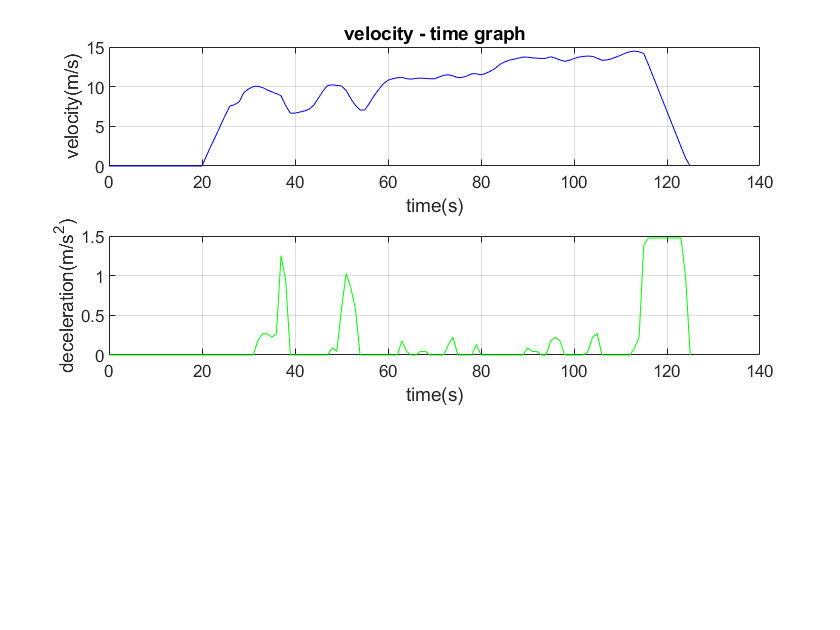


for i= 1:(length(velocity)-1)
    if velocity(i) > velocity(i+1)
        decrease_in_velocity(i) = velocity(i+1) - velocity(i);
        change_in_time(i) = time(i+1)-time(i);
        deceleration(i) = -decrease_in_velocity(i)/change_in_time(i);
        braking_energy(i) = 0.5*mass*((velocity(i)^2) - (velocity(i+1)^2));
       
      
        if mass*deceleration(i)<= Rolling_resistance
           Rolling_resistance = 0;
        else
              braking_force(i) = mass*deceleration(i)-(Rolling_resistance); 
            braking_torque(i)= braking_force(i)*R;
        
        Power(i) = braking_energy(i)/time(i);
        Voltage(i) = (4*N*B*L*Rx*Power(i))/braking_torque(i);
        end
        
    end
end
figure
subplot(3,1,1)
plot(time,velocity, 'b')
grid
xlabel('time(s)')
ylabel('velocity(m/s)')
title('velocity - time graph')

subplot(3,1,2)
plot(time,deceleration, 'g')
grid
xlabel('time(s)')
ylabel('deceleration(m/s^2)')

**For Braking force**

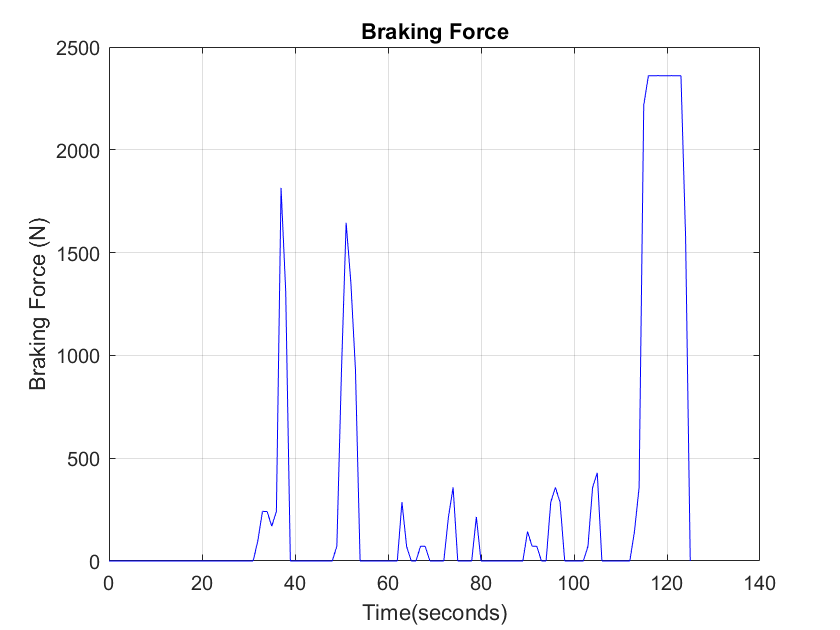

figure
plot(time,braking_force,'b');
grid
xlabel('Time(seconds)')
ylabel('Braking Force (N)')
title('Braking Force')

## For Braking Torque

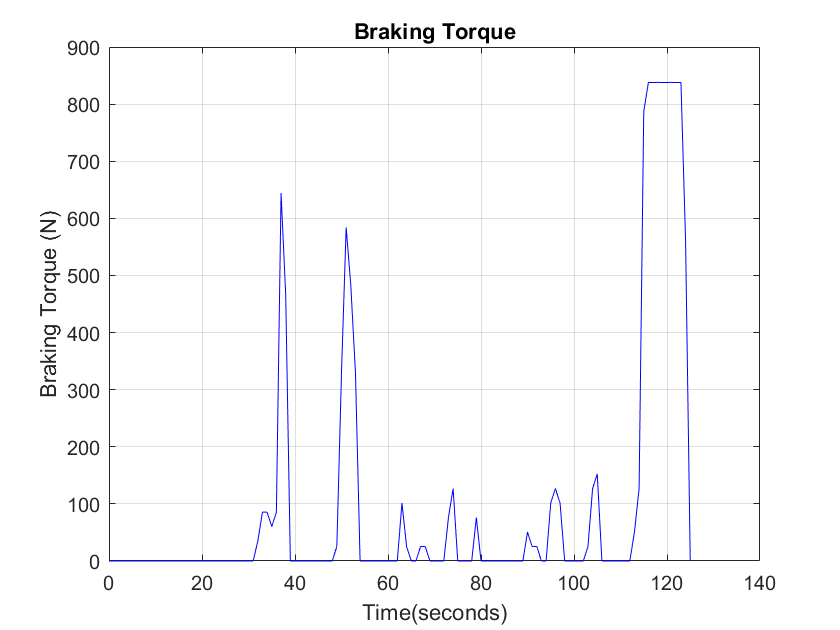

figure
plot(time,braking_torque,'b');
grid
xlabel('Time(seconds)')
ylabel('Braking Torque (N)')
title('Braking Torque')

## For EMF

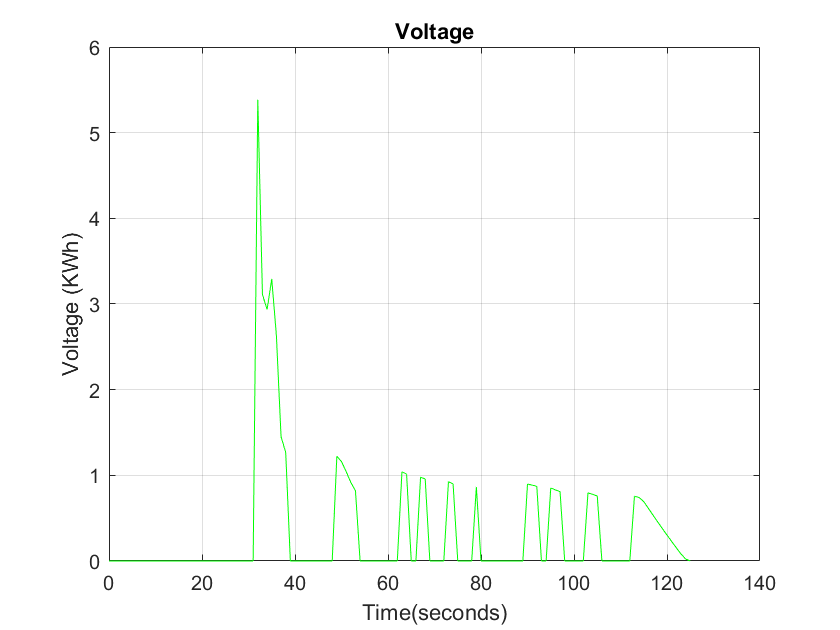

figure
plot(time, Voltage, 'g')
grid
xlabel('Time(seconds)')
ylabel('Voltage (KWh)')
title('Voltage')

## For Power

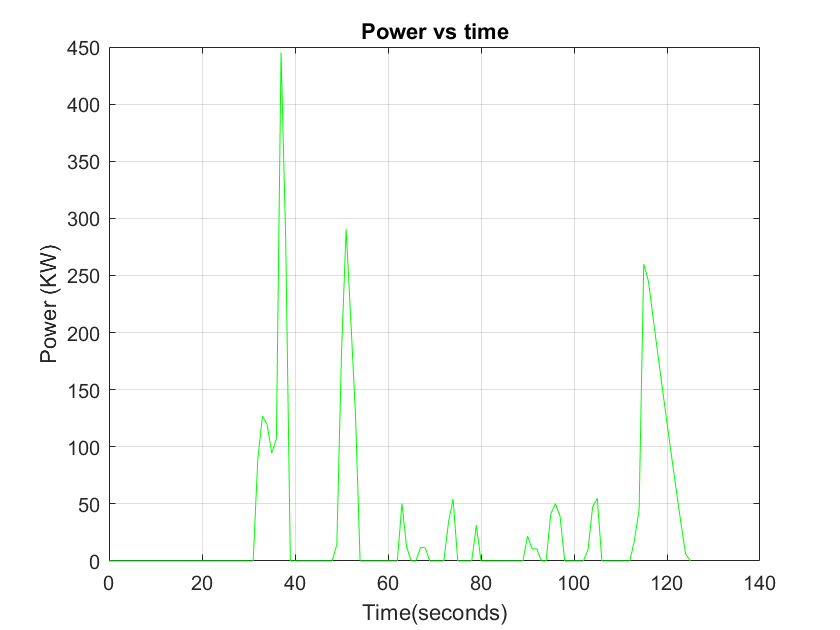

figure
plot(time, Power, 'g')
grid
xlabel('Time(seconds)')
ylabel('Power (KW)')
title('Power vs time')

## For Braking Energy

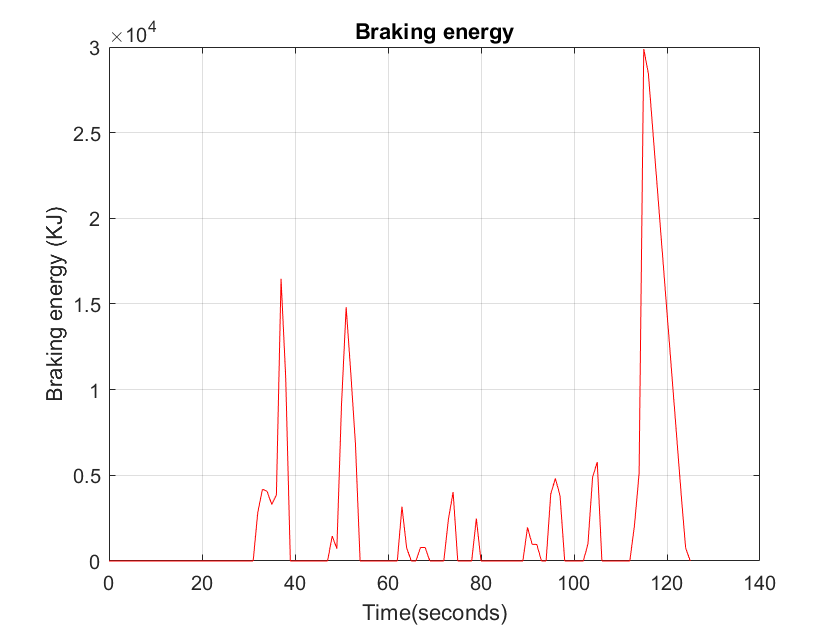


figure
plot(time, braking_energy, 'r')
grid
xlabel('Time(seconds)')
ylabel('Braking energy (KJ)')
title('Braking energy')


fprintf('The required braking energy for given vehicle in given drive cycle is %d \n', sum(braking_energy));

The required braking energy for given vehicle in given drive cycle is 2.997879e+05 


sum(braking_torque)

ans = 1.2635e+04

sum(Power)

ans = 4.0100e+03

sum(Voltage)

ans = 44.3680